# Exploration of Cyclical Control

a Robust Controls method applied to Mechatronic Systems

By Brian Lesko, 

Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robust Controls 8352 | Ohio State University | 12/5/2022

with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc

## Previous work 

    The Qube servo plant used in this demonstrstion has been studied previously. During this previous work, time and frequency responses have been documented when implementing a variety of controller design methods. First, D-stability, margin bounds, and mixed sensitivity were used to achieve a multi-objective design by producing a controller parameter space. Next, analytical methods were used to produce a lead-lag and then PID controller - where the same procedures were repeated for numerous increases in the plant time constant. 

## Controls Background

    Repetitive Control is a method to reduce input to output tracking error within a control system that has a periodic refrence or disturbance input with a known period. Repetitive controller use a time delay, which increases difficulty in predicting stability - here, regeneration spectrum <1 is used as a stability condition. A low pass filter is used to turn off repetitive control at frequencies higher than its bandwidth. Repetitive control has been used for trajectory control of robot arms, cold rolling machining, control of hard disk drives, motor speed control, among many other uses. 

# Repetitive Control Block Diagram used

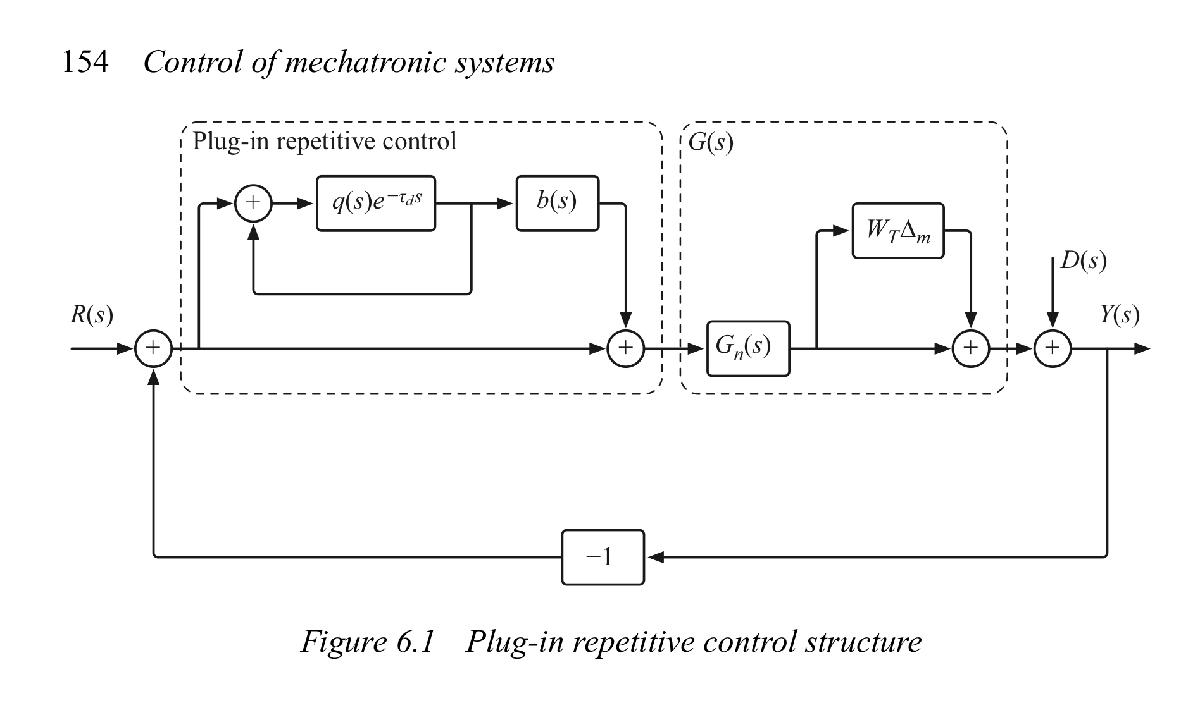

Robust Control of Mechatronic Systems

clc; clear; close all;
%Angular Position Plant
s = tf('s'); tau_n = 0.1; K_n = 28;
Gn = K_n / (tau_n*s + 1)/s

Gn =
 
      28
  -----------
  0.1 s^2 + s
 
Continuous-time transfer function.



# Repetitive Control Design

design (b filter, q filter bandwidth, R(ω), phase advances)

% b Filter should approximately invert G/(1+G)
bp_num = 10/7*s^2 + 100/7*s +400;
bp_den = s^2 + 40*s +400;
bp = bp_num/bp_den;
b = bp*exp(-0.1*s); % with a small time advance to eliminate the phase shift for the regeneration spectrum 

% The Q filter should be a low pass filter
qp = 280 / (s^2+10*s+280);
q = qp*exp(-0.04*s);

% The Regeneration Spectrum is minimized with these choices
% The phase advance is added to cancel phase to reduce steady state error

# Model Uncertainty 

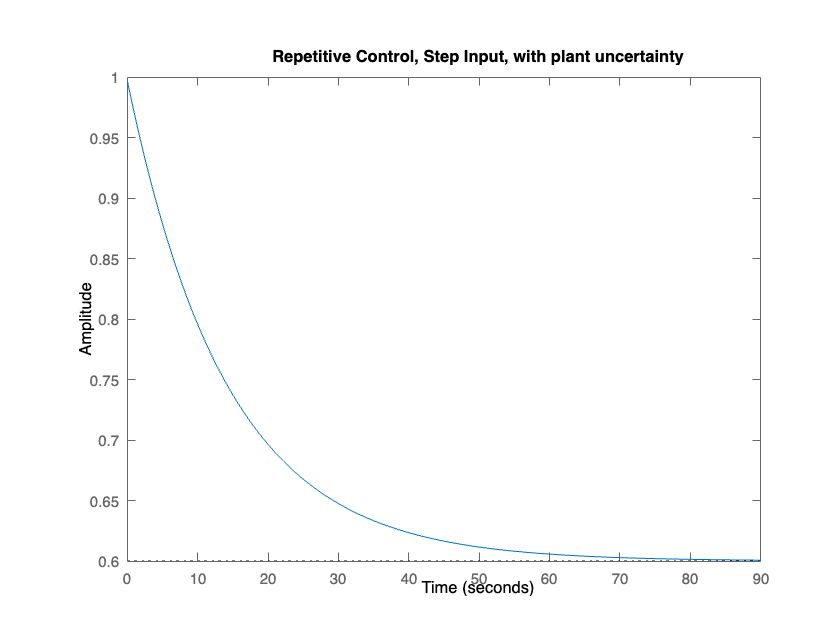

% 25% increase in parameters, "Unexpected" Actual Plant
increase = 1.12;
K = K_n * increase; 
tau = tau_n * increase; 
tau_d = 0;
G = K / (tau*s + 1) * exp(tau_d * s); %%%
uncertainty_bound = Gn/(G-Gn);

delta_m = 1/uncertainty_bound;
%where Wt is the sensitivity of the complimentary sensitivity function
Wt = 1;

disturbance = 0;
repetitiveController = 1+feedback(q,+1)*b; 
plantUncertainty = G*(Wt*delta_m + 1);
y_r = feedback(repetitiveController + plantUncertainty + disturbance,1);
figure(), step(y_r)
title('Repetitive Control, Step Input, with plant uncertainty')

The step input is not followed. Further exploration is reccomended.

Sine Wave Input

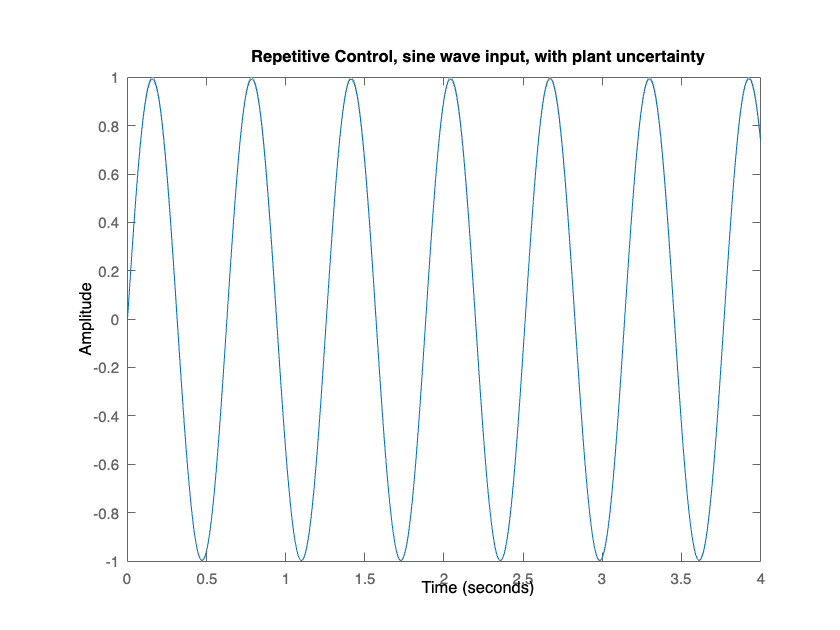

figure()
t = 0:0.01:4; u = sin(10*t); % u,t define the input signal
lsim(y_r,u,t) %Arbitrary sin wave Response
title('Repetitive Control, sine wave input, with plant uncertainty')

The plant output very closely matches the desired input despite the plant uncertainty

# Disturbance Input

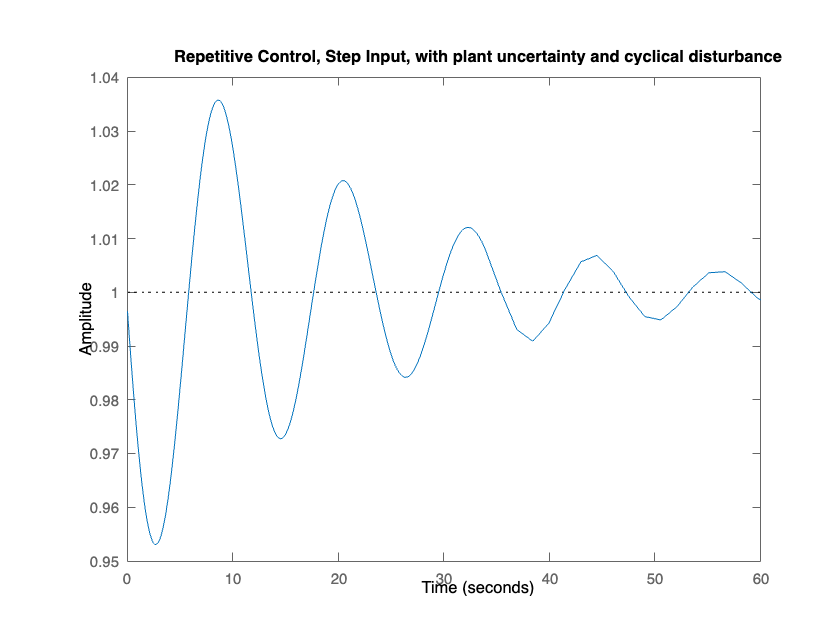

% 25% increase in parameters, "Unexpected" Actual Plant
increase = 1.12;
K = K_n * increase; 
tau = tau_n * increase; 
tau_d = 0;
G = K / (tau*s + 1) * exp(tau_d * s); %%%
uncertainty_bound = Gn/(G-Gn);

delta_m = 1/uncertainty_bound;
% where Wt is the sensitivity of the complimentary sensitivity function
Wt = 1;

% The Disturbance Input, Laplace domain sin wave
disturbance = exp(-.1*s)/(1-exp(-.1*s));

repetitiveController = 1+feedback(q,+1)*b; 
plantUncertainty = G * (Wt*delta_m + 1);
y_r = feedback(repetitiveController+plantUncertainty + disturbance,1);
figure(), step(y_r)
title('Repetitive Control, Step Input, with plant uncertainty and cyclical disturbance')

A -4% undershoot slowly dissapears as the steady state error approaches the correct step input despite the disturbance 

Sine Wave Input

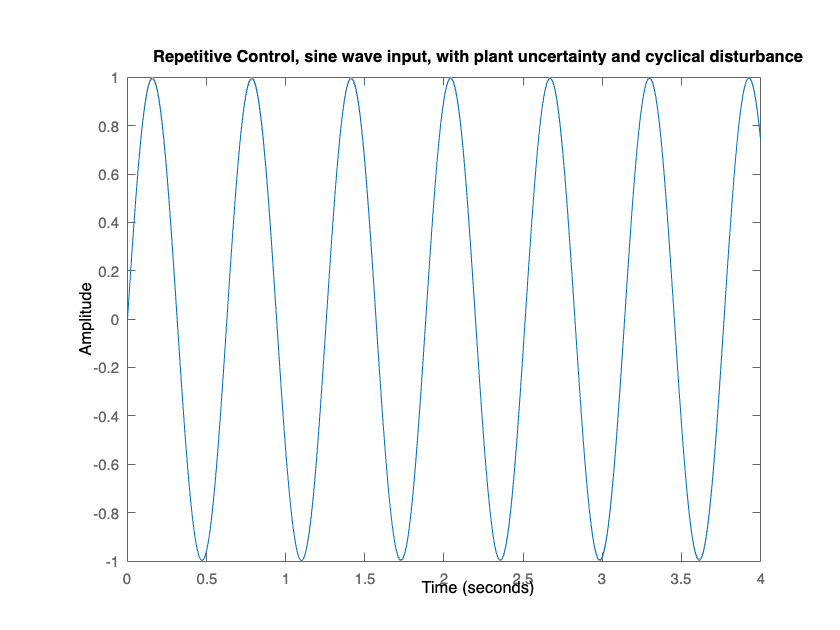

figure()
t = 0:0.01:4; u = sin(10*t); % u,t define the input signal
lsim(y_r,u,t) %Arbitrary sin wave Response
title('Repetitive Control, sine wave input, with plant uncertainty and cyclical disturbance')

The plant output very closely matches the desired input despite the cyclical disturbance